Q-8

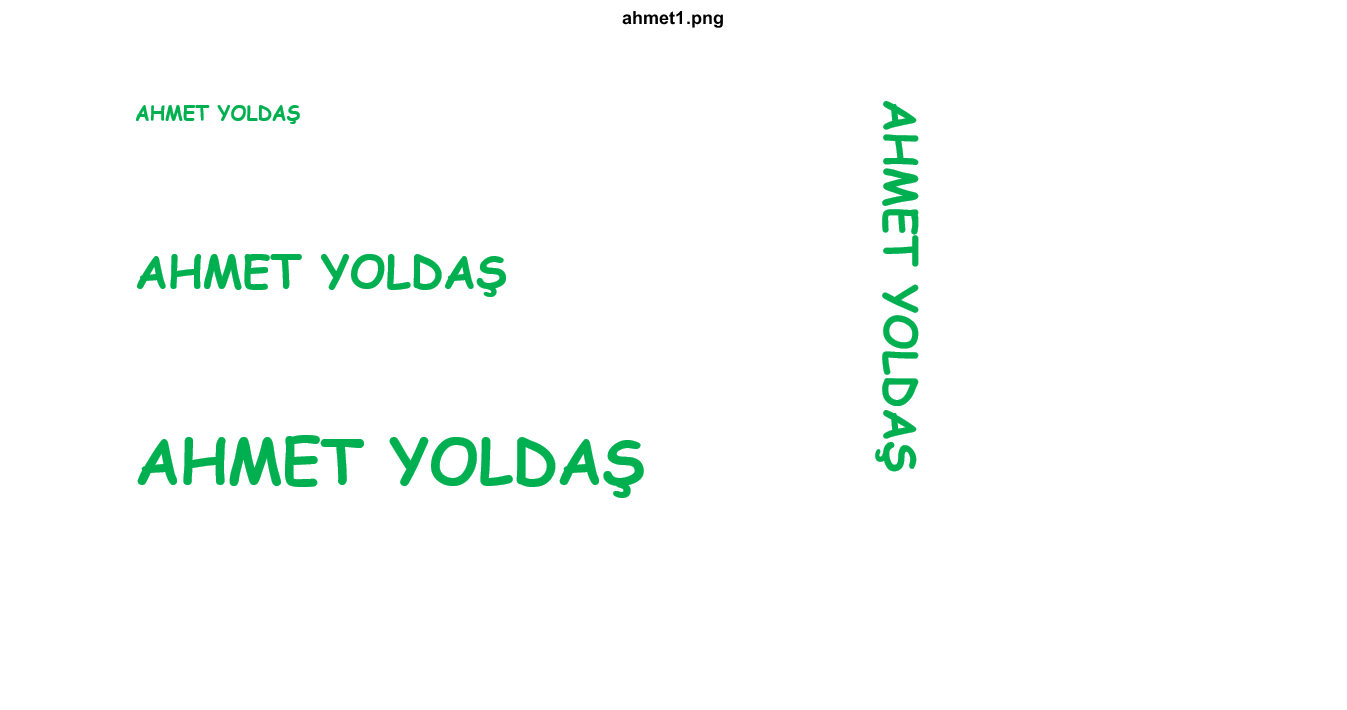

ahmet=imread('C:\Users\ahmet\Desktop\ahmet1.png');
figure;
imshow(ahmet);
title('ahmet1.png');

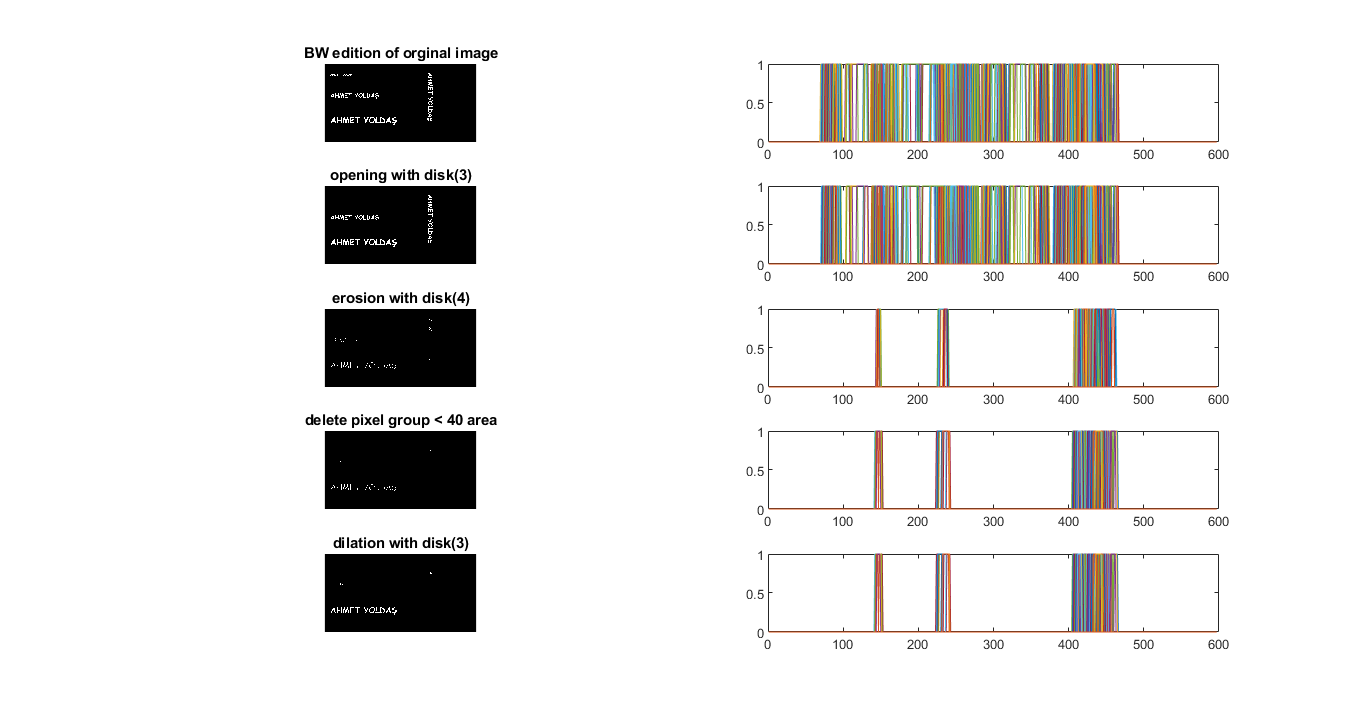

b_ahmet=imbinarize(rgb2gray(im2double(ahmet)));
b_ahmet=abs(b_ahmet-1);

subplot(521)
imshow(b_ahmet);
title('BW edition of orginal image');
mask1= strel('disk',3);
small_ahmet=imopen(b_ahmet,mask1);
mask2 = strel('disk',4);

subplot(522)
plot(b_ahmet);
subplot(523)
imshow(small_ahmet);
title('opening with disk(3)');
medium_ahmet=imerode(b_ahmet,mask2);
subplot(524)
plot(small_ahmet);

subplot(525)
imshow(medium_ahmet);
title('erosion with disk(4)');
medium_ahmet=bwareaopen(medium_ahmet,40);

subplot(526)
plot(medium_ahmet);

subplot(527)
imshow(medium_ahmet);
title('delete pixel group < 40 area');
medium_ahmet=imdilate(medium_ahmet,mask1);

subplot(528)
plot(medium_ahmet);

subplot(529)
imshow(medium_ahmet);
title('dilation with disk(3)'); 

subplot(5,2,10) 
plot(medium_ahmet);